clear all;
N=50;
M=50;
K=10;
sigma1=2;
sigma2=2;
x=1:N;
y=1:M;
a=M*rand(K,1);
b=N*rand(K,1);
xc=zeros(size(x));
yc=zeros(size(y));
for i=1:size(x)
    for j=1:size(a)
        if j==i
            xc(i)=j
        end
    end
end

xc =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i=1:size(y)
    for j=1:size(b)
        if j==i
            yc(i)=j
        end
    end
end

yc =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


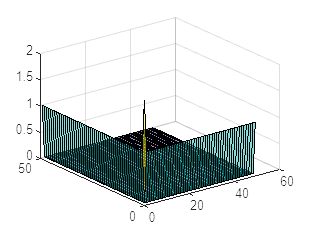

[X,Y]=meshgrid(x,y);
xc=ceil(xc);
yc=ceil(yc);
[XC,YC]=meshgrid(xc,yc);
Z=exp(-(X-XC)^2./sigma1^2)+exp(-(Y-YC)^2./sigma2^2);
figure();
surf(X,Y,Z,'FaceAlpha',0.5);